# Figure 10

## load data

whichData    = 'fmri1'; 
dataLoc      = fullfile(temporalfMRIRootPath, 'files');

[a, b]       = loadfiles(dataLoc, whichData);
data_origDim = a.(whichData).data; % dimensions: 4 subjects x 9 rois x 100 bootstraps x 13 temporal conditions
roiNms       = a.(whichData).nm;

nBoots       = 100; % number of bootstraps

data = squeeze(mean(data_origDim));
ttc  = b.(whichData).ttc; % two-temporal channels model
stn  = b.(whichData).stn; % normalization implementation of the compressive temporal summation model

## compute mean and std for data and model fit

% prep for computing the R2


% compute x-validated R2 fro the two temporal channels model

datars = reshape(permute(data, [2, 1, 3]), [size(ttc.xPrd, 2), 13]);

for k = 1 : size(ttc.xPrd, 2)
   ttc_xr2(k) = [1 - sum((ttc.xPrd(:, k) - datars(k, :)').^2)/sum(datars(k, :).^2)]*100;  
end

mdata = squeeze(mean(data, 2));
sdata = squeeze(std(data, [], 2));

for k = 1 : length(roiNms)
    % for both model fit
    idx = (k - 1) * nBoots + 1 : k * nBoots;
    mttc(k, :) = mean(ttc.prd(idx, :));
    sttc(k, :) = std(ttc.prd(idx, :));
    
    mstn(k, :) = mean(stn.prd(idx, :));
    sstn(k, :) = std(stn.prd(idx, :));
    
    % for x-validated r2
    m_stnr2(k) = median(stn.xr2(idx));
    m_ttcr2(k) = median(ttc_xr2(idx));
    s_stnr2(k, :) = prctile(stn.xr2(idx), [25, 75]);
    s_ttcr2(k, :) = prctile(ttc_xr2(idx), [25, 75]);
    
    % compute the difference between model fit and data
    stn_diff(k, :) = mstn(k, :) - mdata(k, :);
    ttc_diff(k, :) = mttc(k, :) - mdata(k, :);
    
    % compute the transient and the sustained weight for the 2-temporal channels model
    ratio = ttc.param(idx, 2)./ ttc.param(idx, 1);
    m_weight_ratio(k)    = median(ratio);
    s_weight_ratio(k, :) = prctile(ratio, [25, 75]);
end

## plot figure

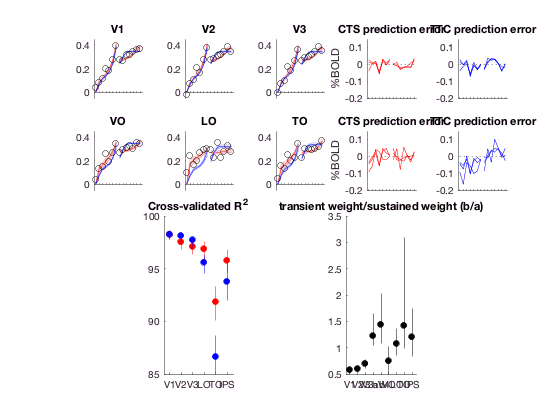

order = [13, 1 : 6, 5, 7 : 12]; roi2Plot = [1, 2, 3; 7, 8, 9]'; subplot_idx = [1, 2, 3, 6, 7, 8];

figure (10), clf
for k = 1 : length(roi2Plot(:))
    subplot(4, 5, subplot_idx(k))
    % plot stn model fit
    shadedErrorBar(1 : 7, mstn(roi2Plot(k), order(1 : 7)), sstn(roi2Plot(k), order(1 : 7)), 'r'), hold on
    shadedErrorBar(8 : 14, mstn(roi2Plot(k), order(8 : 14)), sstn(roi2Plot(k), order(8 : 14)), 'r'),
    
    % plot ttc model fit
    shadedErrorBar(1 : 7, mttc(roi2Plot(k), order(1 : 7)), sttc(roi2Plot(k), order(1 : 7)), 'b'), 
    shadedErrorBar(8 : 14, mttc(roi2Plot(k), order(8 : 14)), sttc(roi2Plot(k), order(8 : 14)), 'b'),
    
    plot(mdata(roi2Plot(k), order), 'ko')
    
    xlim([0.5, length(order)+0.5]), ylim([-0.05, 0.45]), box off,
    set(gca, 'xaxislocation', 'origin', 'xtick', 1 : length(order), 'xticklabel', []),
    title(roiNms(subplot_idx(k)))
end

% plot the difference between model fit and data
subplot_idx = [4, 9];
for k = 1 : 2
    subplot(4, 5, subplot_idx(k)), 
    plot(1 : 7, stn_diff(roi2Plot(:, k), order(1 : 7)), 'r'), hold on
    plot(8 : 14, stn_diff(roi2Plot(:, k), order(8 : 14)), 'r'),ylim([-0.2, 0.15]), xlim([0.5, length(order) + 0.5])
    plot([1, length(order)], [0, 0], 'k:')
    box off, set(gca, 'xtick', 1 : length(order), 'xticklabel', {}),  ylabel('%BOLD'), title('CTS prediction error')
    
    subplot(4, 5, subplot_idx(k) + 1)
    plot(1 : 7, ttc_diff(roi2Plot(:, k), order(1 : 7)), 'b'), hold on
    plot(8 : 14, ttc_diff(roi2Plot(:, k), order(8 : 14)), 'b')
    
    ylim([-0.2, 0.15]), xlim([0.5, length(order) + 0.5])
    box off, set(gca, 'xtick', 1 : length(order), 'xticklabel', {})
    plot([1, length(order)], [0, 0], 'k:'), title('TTC prediction error')
end

% compare r2
subplot(4, 5, [12, 17]), cla
plot(m_stnr2([1 : 3, 7: 9]), 'ro', 'markerfacecolor', 'r'), hold on, 
plot(m_ttcr2([1 : 3, 7 : 9]), 'bo', 'markerfacecolor', 'b')
count = 0;
for k = [1, 2, 3, 7, 8, 9] %roi2Plot(:) 
   count = count + 1;
   plot([count, count], s_stnr2(k, :), 'r-')
   plot([count, count], s_ttcr2(k, :), 'b-')
end
ylim([85, 100]), xlim([0.5, 6.5]), box off, set(gca, 'xtick', 1 : 6, 'xticklabel', roiNms(roi2Plot(:)))
title('Cross-validated R^2')

% plot the ratio between the transient and the sustained weight
subplot(4, 5, [14, 19]), cla
plot(m_weight_ratio, 'ko', 'markerfacecolor', 'k'), hold on
for k = 1 : length(roiNms)
   plot([k, k], s_weight_ratio(k, :), 'k-') 
end
set(gca, 'xtick', 1 : length(roiNms), 'xticklabel', roiNms)
box off, xlim([0.5, length(roiNms) + 0.5]), ylim([0.5, 3.5])
title_txt = 'transient weight/sustained weight (b/a)';
title(title_txt),